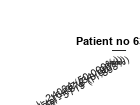

datasets = preprocessDatasets();

for i=1:length(datasets)
    dataset = datasets{i};
    analyseDataset(dataset);
    [dataset.FeatVectSel, dataset.Trg] = ...
    classBalance(dataset.(ESPConst.PROP_DATASET_FEATURES), ...
        dataset.(ESPConst.PROP_DATASET_CLASSES), ...
        1);
    pause(2);
    analyseDataset(dataset);
    pause(2);
end